# Introduction to the optical image

**ISET** is organized around several key objects (scene, optics, sensor, processor and display) that reflect the important parts of the image acquisition pipeline. ISET calculations are based on these objects. By using these objects properly, the code and analysis are much easier to understand.

This script illustrates how to compute the ISET **optical image** (OI). The OI is the spectral irradiance at the sensor surface, after the scene passes through the optics. The optics data are stored in a slot within the OI structure.

Use t_"TAB KEY" to see the list of tutorials 

Use s_"TAB KEY" to see the list of ISET scripts.

See also: oiCompute, oiCreate, t_oiCompute.

Copyright ImagEval Consultants, LLC, 2012.

## Initialize ISET

ieInit

## Create a point array scene

This and other simple synthetic scenes are useful for examining simple optical properties

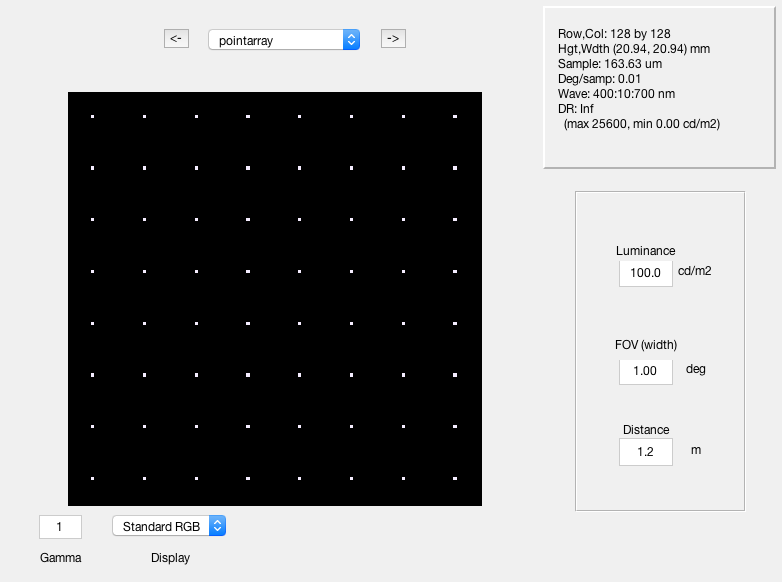

scene = sceneCreate('point array');  % Creates an array of points
scene = sceneSet(scene,'hfov',1);    % 1 deg field of view
ieAddObject(scene); sceneWindow;

## Create and show an optical image

ISET has several optics models that you can experiment with. These include shift-invariant optics, in which there is a different shift-invariant pointspread function for each wavelength, and a ray-trace method, in which we read in data from Zemax and create a shift-variant set of pointspread functions along with a geometric distortion function. The default optical image has diffraction limited optics.  We compute the irradiance field from the scene.

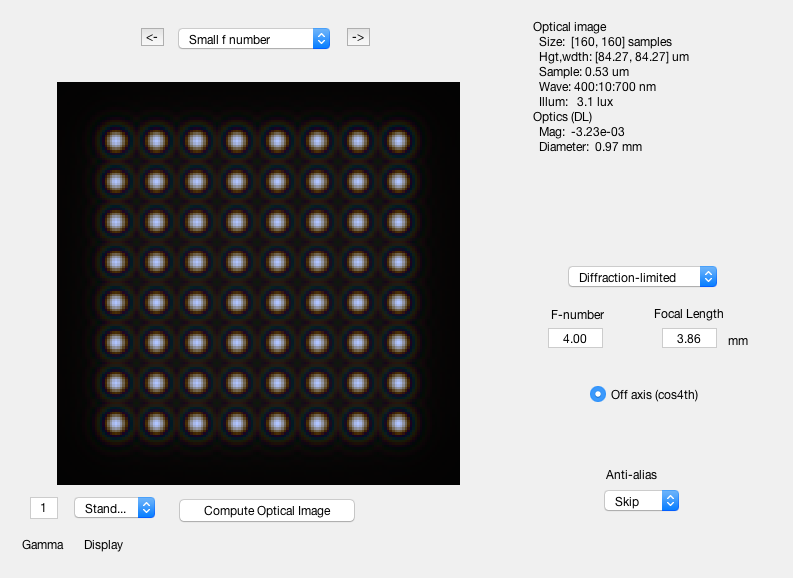

oi = oiCreate;                        
oi = oiCompute(scene,oi);
oi = oiSet(oi,'name','Small f number');
ieAddObject(oi); oiWindow;

## Increase the f# of the optics and compute again.

Increasing the f-number of the optics will blur the irradiance image. The optics structure is attached to the optical image. To increase the f-number we get the optics object, set its fnumber, and then reattach it to the optical image.

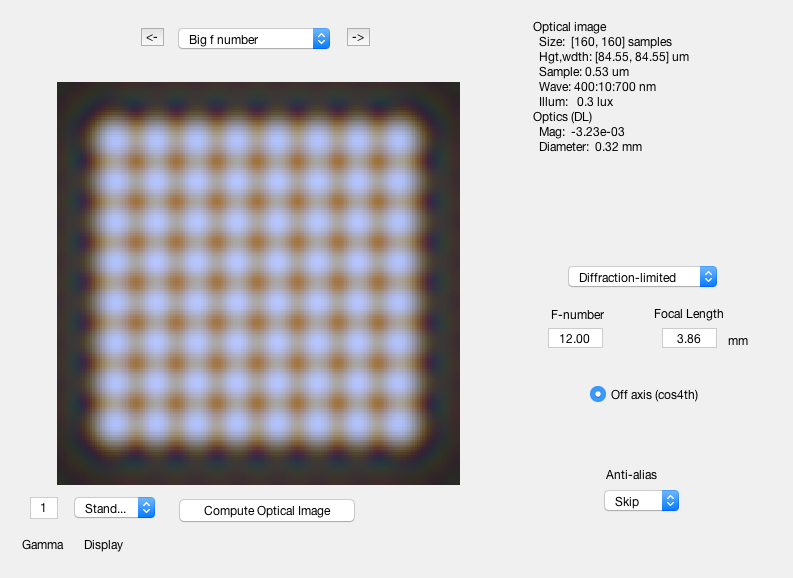

fnSmall = oiGet(oi,'optics f number');
fnBig   = 3*fnSmall;
oiBigF = oiSet(oi,'optics f number',fnBig);
oiBigF  = oiCompute(scene,oiBigF);

oiBigF  = oiSet(oiBigF,'name','Big f number');
ieAddObject(oiBigF); oiWindow;

## Use oiPlot to compare the two different optics

In this case we plot the point spread function at 600 nm.  First for the small f/#.

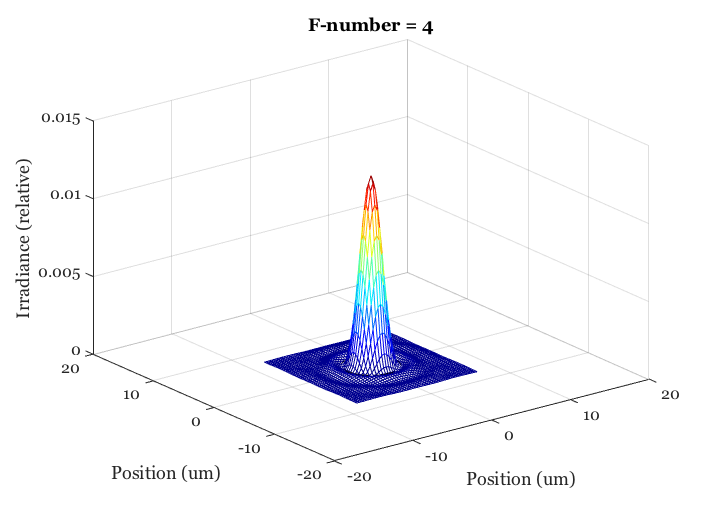

thisWave = 600;

% Most ISET plotting routines can return the plotted data into a variable
pData = oiPlot(oi,'psf',[], thisWave);   
set(gca,'xlim',[-20 20],'ylim',[-20 20])
title(sprintf('F-number = %d',fnSmall))


% Here are the values returned by oiPlot
pData

pData = struct with fields:
      x: [50×50 double]
      y: [50×50 double]
    psf: [50×50 double]


## Show the effect of the larger f/# on the PSF

This is for the larger f/#.  We just show a 20 um square region.

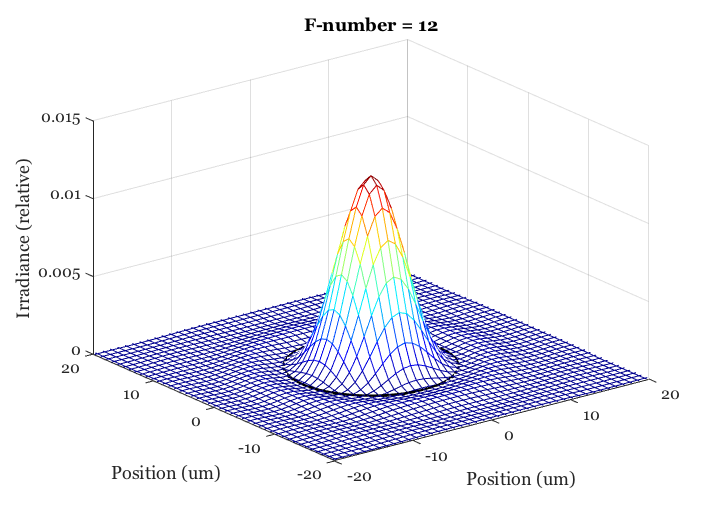

oiPlot(oiBigF,'psf',[], thisWave);
set(gca,'xlim',[-20 20],'ylim',[-20 20])
title(sprintf('F-number = %d',fnBig))


% We can also get the plotted values from the figure
pData = get(gcf,'userdata');
pData

pData = struct with fields:
      x: [50×50 double]
      y: [50×50 double]
    psf: [50×50 double]


## Use oiPlot to quantify the optical image

This example plots an RGB representation of the irradiance field in the optical image.

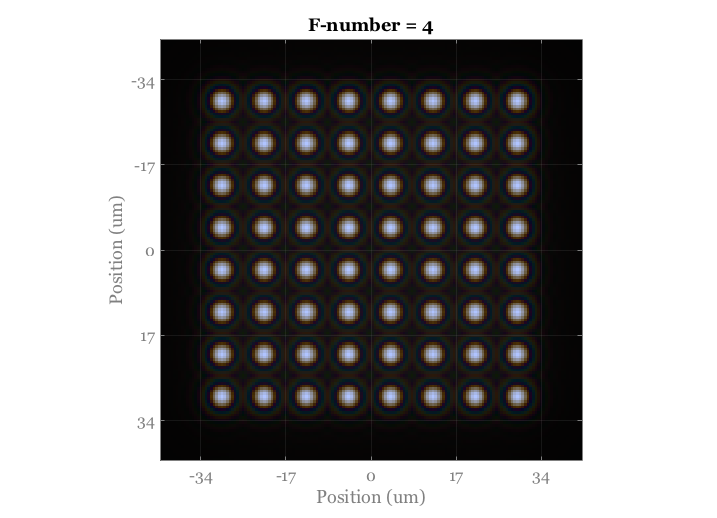

xy = [];        % Irrelevant variable for this plot
gSpacing = 17;  % The grid spacing in microns
oiPlot(oi,'irradiance image with grid',xy,gSpacing);
title(sprintf('F-number = %d',fnSmall))

## Plot an RGB representation of the new irradiance field

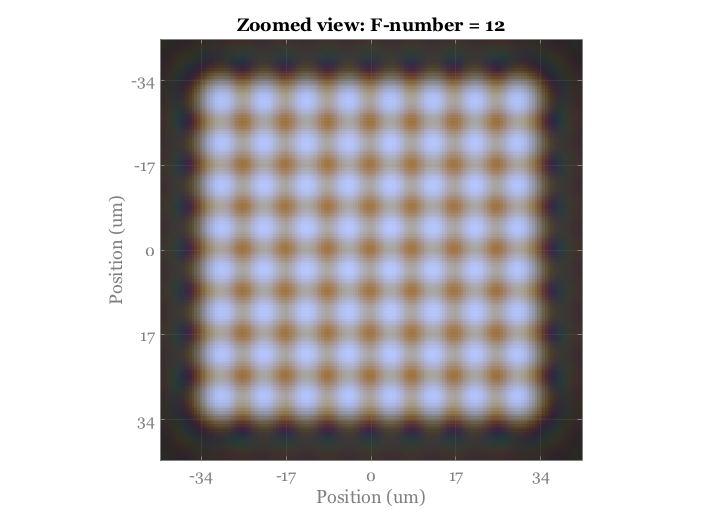

xy = []; gSpacing = 17;
oiPlot(oiBigF,'irradiance image with grid',xy,gSpacing);
title(sprintf('Zoomed view: F-number = %d',fnBig))

## Now, run using parameters from human optics

The defcous of the human optics in the short wavelength light is very large.  That is illustrated in this example.  Try to understand why the center of the dots now look yellow!

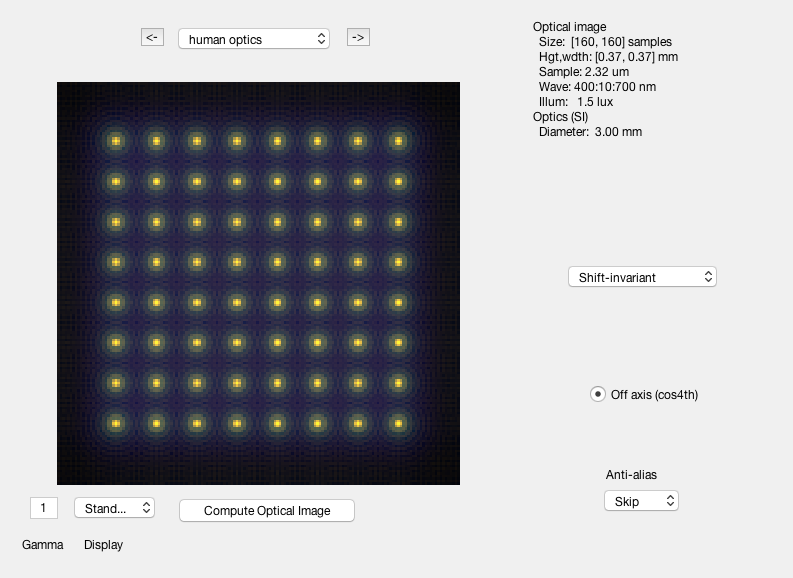

oiHuman = oiCreate('human');
oiHuman = oiCompute(scene,oiHuman);
oiHuman = oiSet(oiHuman,'name','human optics');
ieAddObject(oiHuman); oiWindow;